# **Title : **`Noise Reduction in MATLAB`

## `Table of Contents`

    `1.` `Introduction`

    `2.`` Inputs, Load Display Image`

    `3.` `Filtering Options`

    `    3.1. ``Gaussian Filter`

    `    3.2.` `Median Filter`

    `    3.3.` `Wiener Filter`

    `    3.4.` `Bilateral Filter`

    `    3.5.` `Average Filter`

    `    3.6. ``Non-Local Means`

    `4.` `Display and Save Processed Image Results`

    `5.`` C`onclusion

## ` 1. Introduction `

`This Live Script explores image denoising in MATLAB through various filters. By applying techniques such as Gaussian, Median, Wiener, Bilateral, Average, and Non-Local Means filters, the script aims to demonstrate their effectiveness in reducing noise. The results are displayed, and the processed image is saved for further analysis.`

##   `2. Inputs, Load Display Image`

% Input file path (live control)
upload_image = "/MATLAB Drive/sample.png"

upload_image = "/MATLAB Drive/sample.png"

% Specify whether to display the noisy image (live control)
display_image = true

display_image = logical
   1


% Choose the noise reduction filter (live control)
filter = "Non-Local Means"

filter = "Non-Local Means"

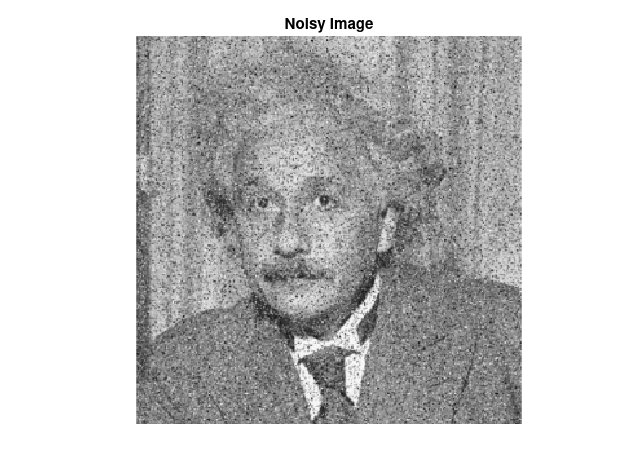

% run button (live control)
 

noisyImage = imread(upload_image);

% Displaying the noisy image if specified
if display_image == 1
    figure;
    imshow(noisyImage);
    title('Noisy Image');
end 

##     `3. Filtering Options`

% Apply the selected noise reduction filter based on the specified filter type
if filter == 'Gaussian Filter'
    filteredImage = imgaussfilt(noisyImage, 1);
elseif filter == 'Median Filter'
    noisyImage = rgb2gray(noisyImage); 
    filteredImage = medfilt2(noisyImage, [3, 3]);
elseif filter == 'Wiener Filter'
    noisyImage = rgb2gray(noisyImage); 
    noisyImage = im2double(noisyImage);
    filteredImage = wiener2(noisyImage, [3, 3]);
elseif filter == 'Bilateral Filter'
    filteredImage = imbilatfilt(noisyImage);
elseif filter == 'Average Filter'
    filteredImage = imfilter(noisyImage, fspecial('average', [3, 3]));
elseif filter == 'Non-Local Means'
    filteredImage = imnlmfilt(noisyImage, 'DegreeOfSmoothing', 30)
end

filteredImage = 300x298x3 uint8 array
filteredImage(:,:,1) =

   125   128   130   128   130   127   121   127   130   126   131   139   151   160   163   162   164   163   169   171   170   176   177   181   176   172   167   165   159   145   131   159   186   180   167   161   154   144   139   152   162   159   154   147   144   144   139   137   147   153   101    89    86   133   154   154   160   176   184   182   178   181   182   180   183   183   179   178   180   178   175   182   185   178   175   176   173   167   168   177   179   178   174   171   169   172   165   176   182   183   182   181   180   179   181   179   178   175   171   169   168   167   160   154   157   167   169   166   166   170   157   155   149   151   152   135   152   166   138   154   164   171   174   174   169   165   172   179   183   182   176   174   180   187   188   183   174   172   181   187   186   180   178   182   186   192   177   146   184   181   160   142   143   155   187   187  

##     `4.` `Display and Save Processed Image Results`

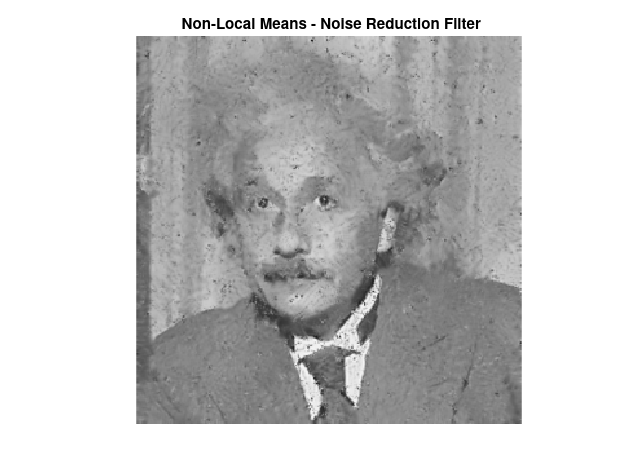


% Display and Saving the filtered image
figure;
imshow(filteredImage);
title(sprintf(' %s - Noise Reduction Filter', filter));
[path, name, ext] = fileparts(upload_image);
newName = name + '_remove_noise';
saveas(gcf,  newName+ '.png');

##     `5.`` C`onclusion

In conclusion, this MATLAB Live Script showcased the versatility of different denoising filters in improving image quality. Each filter demonstrated unique characteristics in noise reduction. Users can choose the most suitable filter based on their specific requirements, contributing to enhanced image processing and analysis in various applications.